# EKF Practice

In this lesson you will have to change constants to make  EKF works properly. 

*Note: Before run this script,  run the rosbag that is in Util folder called EKF rosbag.bag*

*rosbag  play ekf_rosbag.bag  *

clear
rosshutdown

Shutting down global node /matlab_global_node_38085 with NodeURI http://dieg0:34331/


rosinit

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
Initializing global node /matlab_global_node_58569 with NodeURI http://dieg0:36825/


Subscribe to odom, odom ground truth and landmarks detection.


sub_odom = rossubscriber("/odom", "nav_msgs/Odometry");
sub_odom_ground = rossubscriber("/odom_ground_truth", "nav_msgs/Odometry");
sub_landmarks = rossubscriber("/landmarks", "custom_msgs/Landmarks");
pause(1)

Tray to change  the following constants to get a good estimate pose.

alpha= [ 0.001 0.001 0.001 0.001 ];

Q=  [0.0001, 0,    0;    
           0,    0.0001, 0;    
           0,    0,    0.0001 ];

R =[0.0001, 0,      0;    
           0,      0.00001, 0;    
           0,      0,      0.0001 ];


Define start  pose

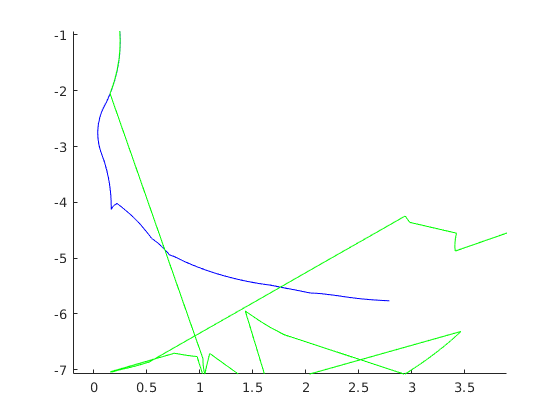

Error using ros.Subscriber/receive (line 430)
The function did not receive any data and timed out.


initPose = [ 0 0 0];
sigma = [0 0 0;  %Covariance matrix start with all elements zero
         0 0 0; 
         0 0 0];

% landmarks position on the environment
landmak_coordinates=[
	2.6501  2.2012 1.0  ;
   -0.8888 -0.9584 8.0  ;
   -0.6514  1.2021 14.0 ;
    4.5925  2.2038 17.0 ;
    5.0717  0.1753 18.0 ;
    5.0740 -2.5365 19.0 ;
    5.0730 -5.2918 20.0 ;
    5.0750 -6.2680 701.0;
   -0.8947  0.8557 702.0;
   -0.8962 -2.2954 703.0;
    4.2305 -6.9905 704.0;
    1.5000  1.7934 705.0;
    1.9894  2.2036 706.0;
   -0.8966 -5.1471 717.0;
   -0.1681 -7.0005 718.0;
    0.7395 -6.9997 719.0;
    3.1140 -6.9984 720.0;
];
     
odom_pose = zeros(3,1000);
odom_pose(:,1) = initPose;

odom_pose_ground = zeros(3,1000);
odom_pose_ground(:,1) = initPose;

ekf_pose = zeros(3,1000);
ekf_pose(:,1) = initPose;


once = true;
count = 1;
count2=1;
while true
   
    %Get landmark detection
    msg_landmarks = receive(sub_landmarks,1);
    detections = zeros(length(msg_landmarks),3);
    it = 1;
    if ~isempty(msg_landmarks.Landmarks_) 
        for i=1:length(msg_landmarks.Landmarks_)
            detections(i,:) = [ msg_landmarks.Landmarks_(i).Distance msg_landmarks.Landmarks_(i).Angle msg_landmarks.Landmarks_(i).Id ];
        end
    end
    
    odom_ground = receive(sub_odom_ground,1); 
    odom = receive(sub_odom,1); 
    quat = [odom.Pose.Pose.Orientation.W() odom.Pose.Pose.Orientation.X() odom.Pose.Pose.Orientation.Y()  odom.Pose.Pose.Orientation.Z()  ];
    eu = quat2eul(quat);
    
    odom_pose(1,count) =  odom.Pose.Pose.Position.X ;
    odom_pose(2,count) =  odom.Pose.Pose.Position.Y ;
    odom_pose(3,count) =  eu(1) ;
    
    odom_pose_ground(1,count) =  odom_ground.Pose.Pose.Position.X ;
    odom_pose_ground(2,count) =  odom_ground.Pose.Pose.Position.Y ;
    odom_pose_ground(3,count) =  eu(1) ;
    
    
    count = count +1;
    if(once)
        once = false;
        o_1 = [ odom.Pose.Pose.Position.X;
                odom.Pose.Pose.Position.Y;
                eu(1)  ];
        initPose=o_1;
        quat_1 = quat;
        sv = initPose;  
    end
    
    %Variables to check how long the robot has moved or turned.
    distance = sqrt( (o_1(1)-odom.Pose.Pose.Position.X)^2 +  (o_1(2)-odom.Pose.Pose.Position.Y)^2  );
    aux = quat2eul(quatmultiply(quatconj(quat_1),quat));
    spin =   abs(aux(1));
    
    if distance >.1 || spin > pi/90  && ~isempty(detections) 

        o = [ odom.Pose.Pose.Position.X;
              odom.Pose.Pose.Position.Y;
              eu(1) ];
        %Execute EKF
        [sv,sigma] = ekf_differential(o_1,o,sv,alpha,sigma,detections,landmak_coordinates,Q,R );
        ekf_pose(1,count2)=sv(1);
        ekf_pose(2,count2)=sv(2);
        count2 = count2+1;
        
        o_1 = o; 
        quat_1 = quat;
    end
    

    %Plot the odom ground truth and EKF estimation
    hold on
    plot(odom_pose_ground(1,1:count-1),odom_pose_ground(2,1:count-1),'b');
    plot(ekf_pose(1,1:count2-1),ekf_pose(2,1:count2-1),'g');
    

    pause(0.1);
    
end